**Q3(b)**

Load data and scatter plot

clear
load points2D_Set1.mat
scatter(x,y)
hold on

Finding Mean and subtracting from data

mx = sum(x)/size(x,1);
my = sum(y)/size(y,1);
x = x-mx;
y = y-my;

Covariance matrix and eigen value decomposition

c = [x'*x , x'*y ; x'*y , y'*y] / size(x,1);
[V, d] = eig(c);
d = diag(d);

Getting the direction of maximum variance(as there are only two eigen values we can use a simple if statement instead of argmax)

if d(1) > d(2)
    u =  V(:,1);
else
    u = V(:,2);
end

Plotting the linear relationship


$$u_1 \left(Y-m_Y \right)=u_2 \left(X-m_X \right)\;\Rightarrow Y=\frac{u_2 }{u_1 }\left(X-m_X \right)+m_Y$$


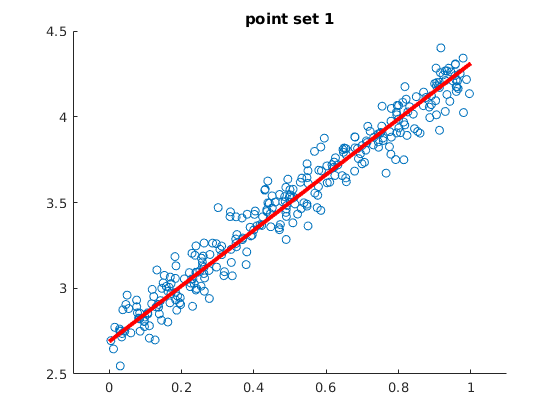

line(xlim, my+u(2)*(xlim-mx)/u(1) ,'LineWidth',3,'Color','red' );
xlim([-0.1 1.1]);
title("point set 1");
hold off

Normalised mean square error

error = sum((y - u(2)*x/u(1)).^2)/(size(x,1)*my*my)

error = 7.4996e-04